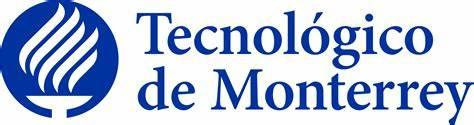

**Examen final.**

**Fundamentación de robótica gpo101**

**Hecho por:**

A01736196 | Abraham Ortiz Castro

 ITESM puebla

**Profesor:**

Alfredo García Suárez.

*11 de marzo del 2024.*

# **Primer ejercicio.**

## Modelo.

Se puede observar que este robot es solamente de un grado de libertad, por lo tanto el análisis es muy sencillo.

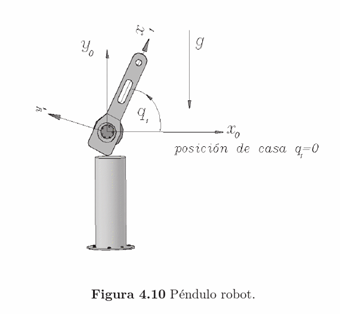

##   **Marco de referencia utilizado.**

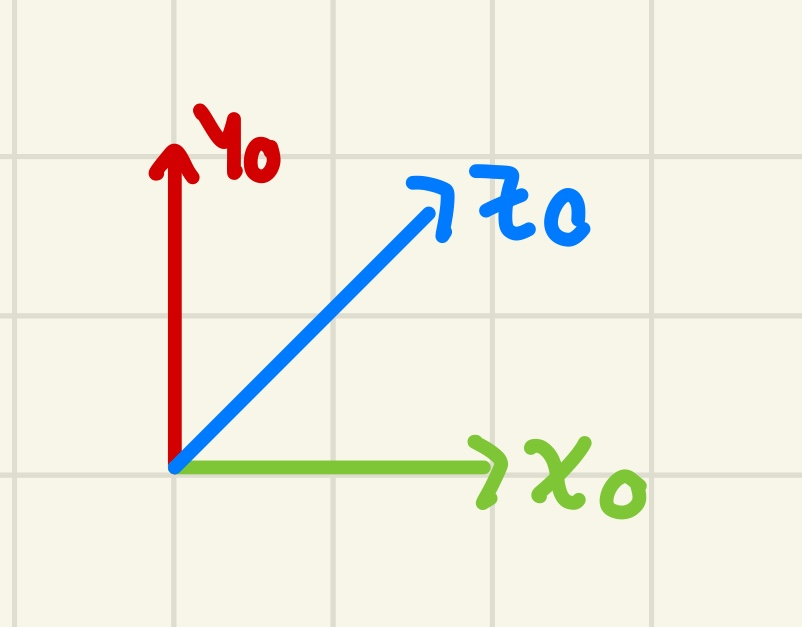

A continuación se podrá observar como fue que se realizó el análisis desde la cinemática del robot hasta poder llegar al análisis de la dinámica del mismo. Se irá explicando el código con la respectiva teoría.

Lo primero que se hace es la limpieza de pantalla y de las variables.

%Limpieza de pantalla
clear all
close all
clc

tic %Se inicializa el contador del tiempo que tarda en correr

Aquí se deben de declarar todas las variables del robot.

th1 es el ángulo que puede variar en el tiempo.

th1p será la derivada del ángulo, por lo tanto la velocidad angular.

th1pp será la segunda derivada del ángulo, por lo tanto la aceleración angular.

m1 es la masa del brazo del robot

Ixx1, Iyy1, ixx1 son los valores que tendrán las matrices de inercia de todos los ejes.

%Declaración de variables simbólicas
syms th1(t) th1p(t) th1pp(t)  t  %Angulos de cada articulación
syms m1 Ixx1 Iyy1 Izz1  %Masas y matrices de Inercia
syms l1 lc1   %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms g cero


En esta parte se han declarado partes importantes del robot, como la coordenadas articulares, configuración del robot, etc.

%Creamos el vector de coordenadas articulares
Q= [th1];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades articulares
Qp= th1p;
%disp('Velocidades generalizadas');
%pretty (Qp);
%Creamos el vector de aceleraciones articulares
Qpp= th1pp;
%disp('Aceleraciones generalizadas');
%pretty (Qpp);

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);


Aquí se define la matriz tanto de rotación como de translación del robot.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);



En esta parte del código se definen todas las configuraciones tanto locales como globales del robot.

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end


Aquí se obtiene el jacobiano lineal de la forma diferencial.

%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11;
              Jv21 ;
              Jv31 ]);
%pretty(jv_d);


En la siguiente sección lo que se va a hacer es calcular el jacobiano lineal y angular de manera analítica. Ya existen unas fórmulas preestablecidas, por lo tanto solamente hay que poner los condicionales para que haga la operación dependiendo sea el caso. Las operaciones son las siguientes:

Para angular.

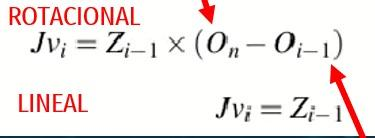

Para prismática.

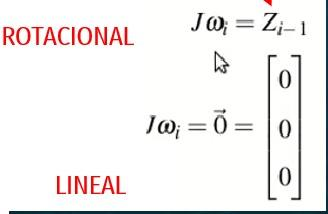

Esto se mete en el código for y queda de la siguiente manera

Se deben de inicializar los jacobianos antes de meterlos al ciclco para determinar el tamaño y que no marque error el código.


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


Se meten los resultados en una matriz completa obteniendo la posición y la orientación.

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac)

$$Jacobiano = \left(\begin{array}{c} -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

Para poder calcular las velocidades lo que se debe de hacer es multiplicar el diferencial de la junta por los jacobianos.

%Obtenemos vectores de Velocidades Lineales y Angulares
% disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
pretty(V);

/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



% disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
 pretty(W);

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



A continuación se obtiene la energía cinética.

Lo primero que se hace es obtener las posiciones respecto al centro de masa (se supone que está en medio del brazo)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
P01=subs(P(:,:,1)/2, l1, lc1); %La función subs sustituye l1 por lc1 en 
                            %la expresión P(:,:,1)/2

Se crean las matrices de incercia para obtener las de los tres ejes.

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
0 Iyy1 0; 
0 0 Izz1];


%Función de energía cinética

Aquí se observa como es que se extraen las velocidad de cada eje.

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos la velocidad angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1

%Ya lo calculamos previamente al multiplicar la matriz jacobiana por Qp

%Calculamos la energía cinética para cada uno de los eslabones


Se suman la velocidad lineal y la angular para producida para poder obtener la energía cinética usando la siguiente fórmula.

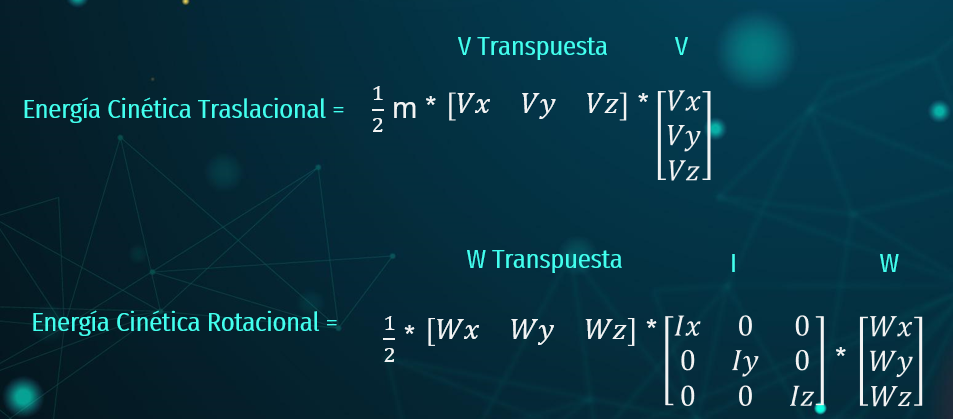

%Eslabón 1
V1_Total= V+cross(W,P01); %Se suma la velocidad lineal producida por la
                      % velocidad angular producida en el punto P01 
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W)'*(I1*W);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2            2     ______           __          2             2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- + -------------------------------------------------------------------------
       2                                           8 l1 lc1





K_Total= simplify (K1);


Aqui se obtiene primero el eje paralelo a la altura y así poder tener la energía potencial.

%Obtenemos las alturas respecto a la gravedad
h1= P01(2); %Tomo la altura paralela al eje y

U1=m1*g*h1;

%Calculamos la energía potencial total
U_Total= U1;



La energía potencial y cinética serán de gran ayuda para obtener el lagrangiano y el modelo de eneríga, usando las fórmulas  que se muestran en el código.

%Obtenemos el Lagrangiano
Lagrangiano= simplify (K_Total-U_Total);
pretty (Lagrangiano);

              2                                   2     ______           __          2             2
Izz1 |th1p(t)|    g lc1 m1 sin(th1(t))   |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- - -------------------- + -------------------------------------------------------------------------
       2                    2                                             8 l1 lc1



%Modelo de Energía
H= simplify (K_Total+U_Total);
pretty (H)

              2                                   2     ______           __          2             2
Izz1 |th1p(t)|    g lc1 m1 sin(th1(t))   |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- + -------------------- + -------------------------------------------------------------------------
       2                    2                                             8 l1 lc1



En esta parte del código es donde se podrá obtener la dinámica del robot usando lo siguiente.

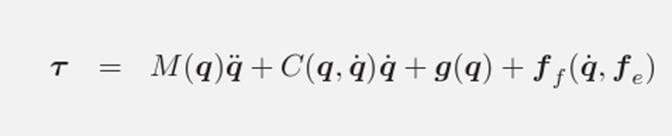

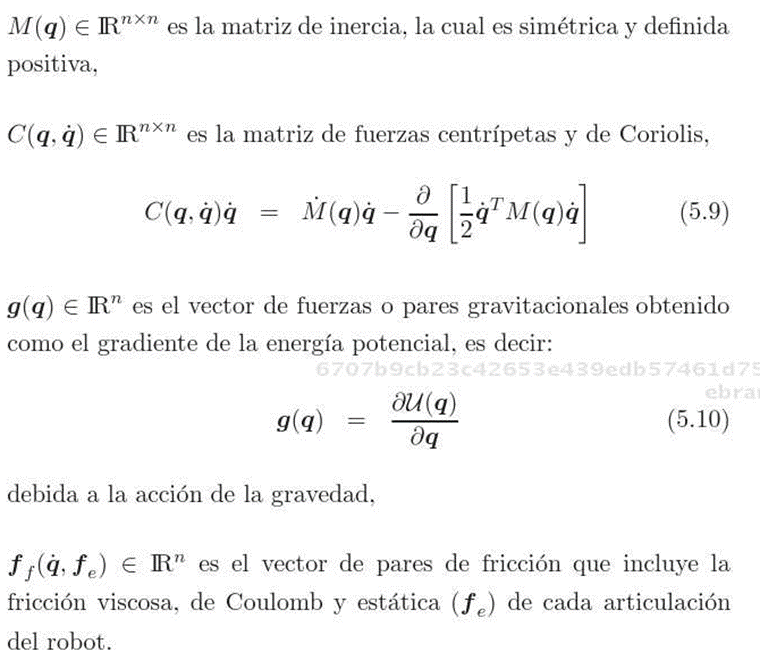

%%%%%%%%%%%%%%%%%%%%%%Ecuaciones de Movimiento%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Lagrangiano derivado con respecto a la primera coordenada generalizada de
%velocidad

%Definimos un vector columna de derivadas con respecto al tiempo
%En este vector agrego las velocidades y aceleraciones
%Derivadas respecto al tiempo
Qd=[th1p(t); th1pp(t)];



A continuación se aplica la siguiente fórmula para obtener el torque.

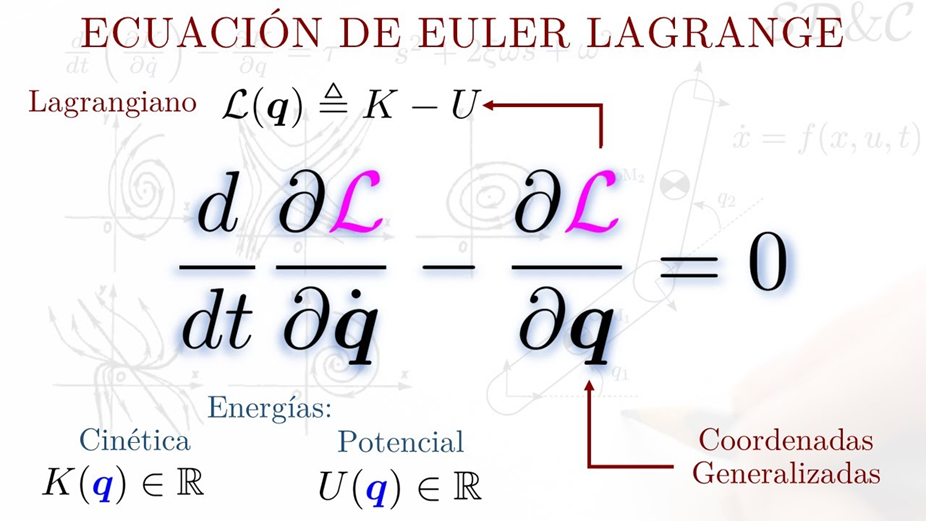

%Obtenemos las derivadas de la velocidad en la primera coordenada
%generalizada
dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th1p)]; %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
 %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

%Definimos el torque 1
t1= dQ1*Qd- diff(Lagrangiano, th1);


Ya teniendo el torque se puede obtener lo siguiente.

La matriz de inercia.


%Generación del Modelo Dinámico en forma matricial

%Matriz de Inercia

%Extraemos coeficientes de aceleraciones

M=[diff(t1, th1pp)]

$$M(t) = \begin{array}{l} {\mathrm{Izz}}_{1}\,{\mathrm{sign}\left(\mathrm{th1p}\left(t\right)\right)}^{2}+2\,{\mathrm{Izz}}_{1}\,\left|\mathrm{th1p}\left(t\right)\right|\,\delta (\mathrm{th1p}\left(t\right))+\frac{\sigma_{2}\,{\mathrm{sign}\left(\mathrm{th1p}\left(t\right)\right)}^{2}\,\bar{m_{1}}\,\sigma_{1}\,\left(2\,l_{1}+{\mathrm{lc}}_{1}\right)}{4\,l_{1}\,{\mathrm{lc}}_{1}}+\frac{\left|\mathrm{th1p}\left(t\right)\right|\,\delta (\mathrm{th1p}\left(t\right))\,\sigma_{2}\,\bar{m_{1}}\,\sigma_{1}\,\left(2\,l_{1}+{\mathrm{lc}}_{1}\right)}{2\,l_{1}\,{\mathrm{lc}}_{1}}\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\\ \sigma_{2}=\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right) \end{array}$$

rank (M);

M=M(t);


La matriz de fuerzas centrípetas y de coriolis.

%Fuerzas Centrípetas y de Coriolis

%Definimos Mp

M11=[diff(M(1,1),th1)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 


Mp=M11;

%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1)];

%Fuerzas centrípetas y de Coriolis
C= Mp*Qp-dk;

Vector de pares gravitacionales.

%Par Gravitacional
%se sustituyen las velocidades y aceleraciones por 0
r=cero;
a1=subs(t1, th1p, r);
a2=subs(a1, th1pp,r);

%Torque gravitacional en el motor 1
G1=a2;


G=G1

$$G(t) = \begin{array}{l} \mathrm{cero}\,\left({\mathrm{Izz}}_{1}\,{\mathrm{sign}\left(\mathrm{cero}\right)}^{2}+2\,{\mathrm{Izz}}_{1}\,\left|\mathrm{cero}\right|\,\delta (\mathrm{cero})+\frac{\sigma_{2}\,\bar{m_{1}}\,{\mathrm{sign}\left(\mathrm{cero}\right)}^{2}\,\sigma_{1}\,\left(2\,l_{1}+{\mathrm{lc}}_{1}\right)}{4\,l_{1}\,{\mathrm{lc}}_{1}}+\frac{\sigma_{2}\,\left|\mathrm{cero}\right|\,\delta (\mathrm{cero})\,\bar{m_{1}}\,\sigma_{1}\,\left(2\,l_{1}+{\mathrm{lc}}_{1}\right)}{2\,l_{1}\,{\mathrm{lc}}_{1}}\right)+\frac{g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\\ \sigma_{2}=\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right) \end{array}$$


toc

Elapsed time is 3.299674 seconds.


# *Segundo ejercicio.*

## ***Modelo*****.**

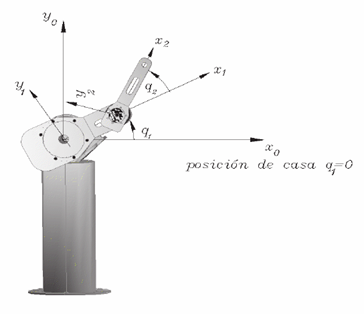

##   **Marco de referencia para determinar las alturas de la energía potencial.**

Se aplica exactamente el mismo proceso y lógica que en el ejercico uno, solamente que en este caso son dos grados de libertad.

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) th2(t) t  %Angulos de cada articulación
syms th1p(t) th2p(t)    %Velocidades de cada articulación
syms th1pp(t) th2pp(t)     %Aceleraciones de cada articulación
syms m1 m2 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 %Masas y matrices de Inercia
syms l1 l2 lc1 lc2  %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2];
 %disp('Coordenadas generalizadas');
 %pretty (Q);
 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p];
 %disp('Velocidades generalizadas');
 %pretty (Qp);
 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp];
 %disp('Aceleraciones generalizadas');
 %pretty (Qpp);

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) 0  -sin(th1);
           sin(th1) 0   cos(th1);
           0       -1         0];

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
% disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
% pretty(V);
% disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
%     pretty(W);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Eslabón 1

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);



%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
%disp('Energía Cinética en el Eslabón 1');
K1= simplify (K1);
%pretty (K1);


%Eslabón 2
V2_Total= V+cross(W,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W)'*(I2*W);
%disp('Energía Cinética en el Eslabón 3');
K2= simplify (K2);
%pretty (K3);

K_Total= simplify (K1+K2);
pretty (K_Total);

                                                                                                                      /            2                           2 \
                    __                                                                                                | #1 #9 |lc2|    #1 #5 #8   #2 #4 #3 |l2|  |
                    m2 (lc2 cos(th2(t)) th1p(t) + cos(th1(t)) th1p(t) (l1 + #6) - l2 sin(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------- - -------------- |
Izz1 #1   Izz2 #1                                                                                                     \  lc2 th1p(t)      #7        l2 th2p(t)   /
------- + ------- + ----------------------------------------------------------------------------------------------------------------------------------------------
   2         2                                                                             2

                                                                                           


%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje z
 h2= P12(2); %Tomo la altura paralela al eje y

 U1=m1*g*h1;
 U2=m2*g*h2;

 %Calculamos la energía potencial total
 U_Total= U1 + U2;

 %Obtenemos el Lagrangiano
 Lagrangiano= simplify (K_Total-U_Total);
 pretty (Lagrangiano);

                                                                                                                      /            2                           2 \
                    __                                                                                                | #1 #9 |lc2|    #1 #5 #8   #2 #4 #3 |l2|  |
                    m2 (lc2 cos(th2(t)) th1p(t) + cos(th1(t)) th1p(t) (l1 + #6) - l2 sin(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------- - -------------- |
Izz1 #1   Izz2 #1                                                                                                     \  lc2 th1p(t)      #7        l2 th2p(t)   /
------- + ------- + ----------------------------------------------------------------------------------------------------------------------------------------------
   2         2                                                                             2

                                                                                           


%Modelo de Energía
 H= simplify (K_Total+U_Total);
  pretty (H)

                                                                                                                      /            2                           2 \
                    __                                                                                                | #1 #9 |lc2|    #1 #5 #8   #2 #4 #3 |l2|  |
                    m2 (lc2 cos(th2(t)) th1p(t) + cos(th1(t)) th1p(t) (l1 + #6) - l2 sin(th1(t)) sin(th2(t)) th2p(t)) | ------------ + -------- - -------------- |
Izz1 #1   Izz2 #1                                                                                                     \  lc2 th1p(t)      #7        l2 th2p(t)   /
------- + ------- + ----------------------------------------------------------------------------------------------------------------------------------------------
   2         2                                                                             2

                                                                                           




%%%%%%%%%%%%%%%%%%%%%%Ecuaciones de Movimiento%%%%%%%%%%%%%%%%%%%%%%%%%%%%

 %Lagrangiano derivado con respecto a la primera coordenada generalizada de
 %velocidad

 %Definimos un vector columna de derivadas con respecto al tiempo
 %En este vector agrego las velocidades y aceleraciones
  %Derivadas respecto al tiempo
 Qd=[th1p(t); th2p(t); th1pp(t); th2pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th2),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), th2p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);


 %Obtenemos las de derivadas de la velocidad en la segunda coordenada
 %generalizada

 dQ2=[diff(diff(Lagrangiano,th2p), th1),diff(diff(Lagrangiano,th2p), th2)... %Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th2p), th1p),diff(diff(Lagrangiano,th2p), th2p)];%Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 velocidades articulaciones

 %Definimos el torque 2
 t2= dQ2*Qd- diff(Lagrangiano, th2);

 


%Generación del Modelo Dinámico en forma matricial

%Matriz de Inercia

%Extraemos coeficientes de aceleraciones

M=[diff(t1, th1pp), diff(t1, th2pp);...
   diff(t2, th1pp), diff(t2, th2pp)];
rank (M);

M=M(t);



 %Fuerzas Centrípetas y de Coriolis
 
 %Definimos Mp

 M11=[diff(M(1,1),th1), diff(M(1,1),th2)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 
 M12=[diff(M(1,2),th1), diff(M(1,2),th2)]*Qp;

 M21=[diff(M(2,1),th1), diff(M(2,1),th2)]*Qp;
 M22=[diff(M(2,2),th1), diff(M(2,2),th2)]*Qp;

  Mp=[M11, M12;...
      M21, M22];


%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk
    
dk=[diff(k, th1); diff(k, th2)];

%Fuerzas centrípetas y de Coriolis
 C= Mp*Qp-dk



 %Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th2p, r);
 a3=subs(a2, th1pp,r);
 a4=subs(a3, th2pp,r);

 %Torque gravitacional en el motor 1
 G1=a4;

 
 b1=subs(t2, th1p, r);
 b2=subs(b1, th2p, r);
 b3=subs(b2, th1pp,r);
 b4=subs(b3, th2pp,r);

 %Torque gravitacional en el motor 2
 G2=b4;


% Vector de par gravitacional

G=[G1;G2]